- `采用相同光谱，不考虑样品色散，仅考虑系统色散（系统色散厚度变化）对白光干涉信号参数、测量结果的影响。改变系统色散厚度变化，观察白光干涉信号变化。分别采用多种方法验证系统色散对白光干涉测量的影响。`对于两光路对称或色散忽略的情形下，干涉条纹强度最大的位置是零光程差对应的零级干涉条纹，零级干涉条纹处的可见度最大。当存在色散时，干涉条纹可见度最大的位置与光强度最大的位置并不重合；若以最大光强度位置作为零光程差会出现四分之一中心波长的系统误差。

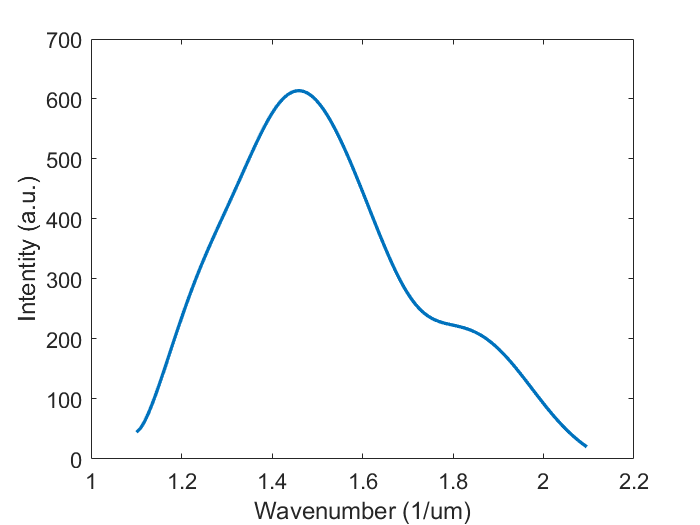

clc; clear all;
%显示光谱信息
format long
spectrum = readtable("Isigma.xls","ReadVariableNames",false);
spectrum_frequency = (spectrum{:,1})';
spectrum_intensity = (spectrum{:,2})';
%disp("全部光谱信息");
% plot(spectrum_frequency,spectrum_intensity)
%找出探测器对应的光谱，这里假设是1.1-2.1
[~, indix_min] = min(abs(spectrum_frequency-1.1));
[~, indix_max] = min(abs(spectrum_frequency-2.1));
spectrum_frequency = spectrum_frequency(indix_min:indix_max);
spectrum_intensity = spectrum_intensity(indix_min:indix_max);
%disp("需要的光谱信息");
plot(spectrum_frequency,spectrum_intensity,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Intentity (a.u.)')
ax = gca;
ax.FontSize = 13;

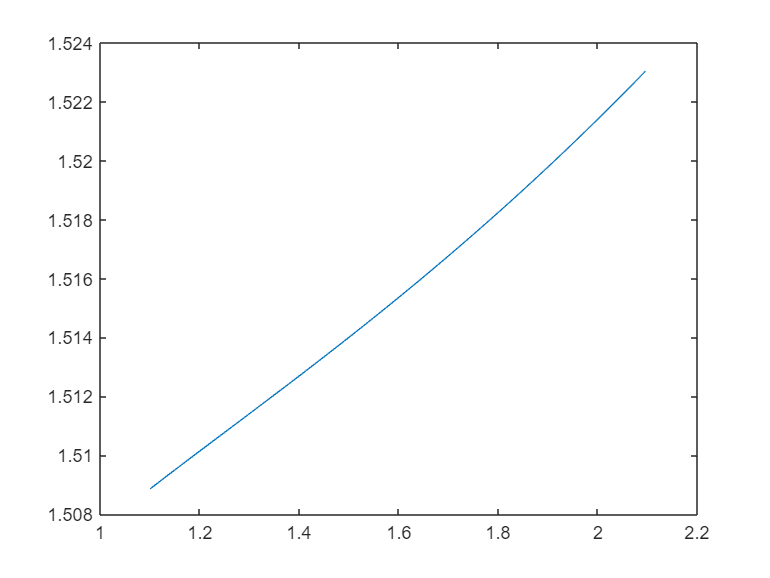


lambda = 1./spectrum_frequency;
index2 = (1.03961212*lambda.^2)./(lambda.^2-0.00600069867)+(1.01046945*lambda.^2)./(lambda.^2-103.560653)+...
        (0.231792344*lambda.^2)./(lambda.^2-0.0200179144)+1; 
index = sqrt(abs(index2));
%折射率曲线
%disp("折射率曲线");
plot(spectrum_frequency,index);

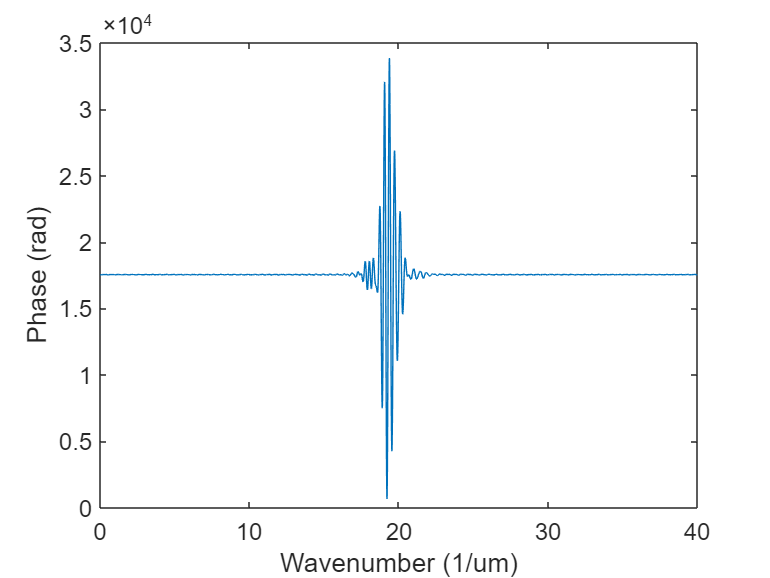

%色散
lEpsilon = 20; %单位为微米
z0 = 30;    %单位为微米
N = 4000;
z = 0:40/4000:(N-1)*(40/4000);
interference_signal1 = zeros(1,length(z));
for i = 1:length(z)
        interference_signal1(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*spectrum_frequency+...
        4*pi*(index-1).*spectrum_frequency*lEpsilon));
end
%disp("生成有色散的白光干涉信号");
plot(z,interference_signal1);
% plot(spectrum_frequency,Phase,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Phase (rad)')
ax = gca;
ax.FontSize = 13;

直接求解最大值：

[max, loc]=max(interference_signal1);
zhijie = z(loc)

zhijie =   19.370000000000001


采用相干峰寻址法测量：高斯包络拟合法（白光干涉光强曲线符合高斯包络调制，对白光 干涉光强的高斯包络进行拟合，取其极值点的横坐 标就是该点对应的相干峰的坐标）

interference_signal = interference_signal1-mean(interference_signal1);
baoluo = hilbert(interference_signal); % Hilbert变换
baoluo = abs(baoluo);
plot(z,interference_signal);
guass = fit(z.',baoluo.','gauss1')

guass =      General model Gauss1:
     guass(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =    1.65e+04  (1.642e+04, 1.658e+04)
       b1 =       19.32  (19.32, 19.32)
       c1 =      0.5974  (0.5941, 0.6008)

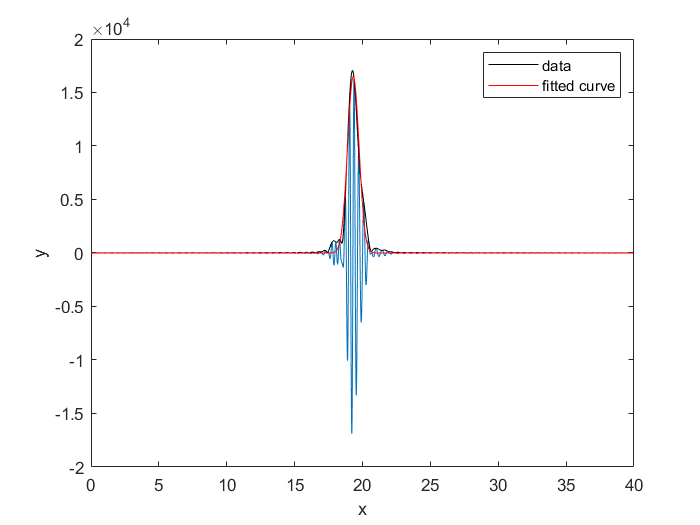

hold on
plot(guass,z,baoluo,'-k')
hold off

baoluoguass = guass.b1

baoluoguass =   19.321572043413187


重心法：

interference_signal = interference_signal1;
zhongxin = zxf(z,interference_signal)

zhongxin =   19.995028654730699


基于相位的测量方法：傅里叶变换法:傅里叶正变换后选择其正频率部分，然后再进行傅里叶逆变换就会得到白光干涉信号的幅度谱和相位谱。

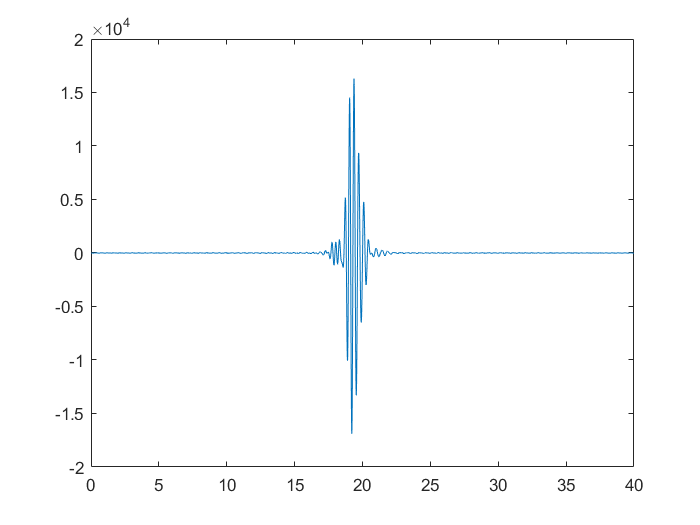

%对光谱进行傅里叶变换
interference_signal = interference_signal1-mean(interference_signal1);
plot(z,interference_signal);

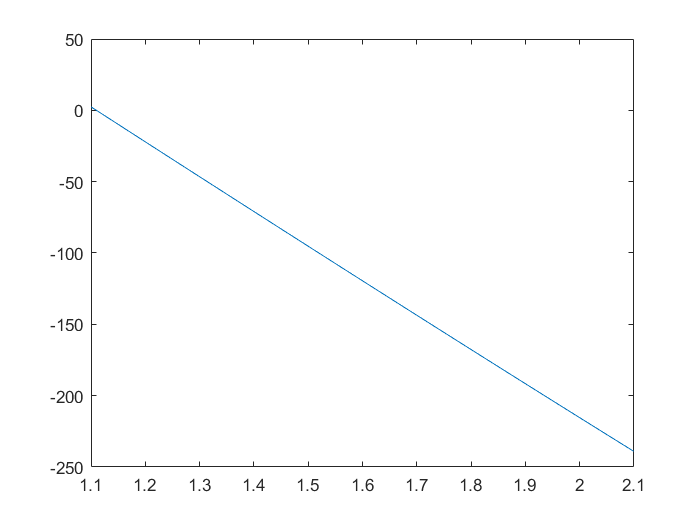

%fft补零
Nftt = 2^15;
f_interference_signal = fft(interference_signal,Nftt);
Fs = 1/(40/4000);
deltaSigma = Fs/(2*Nftt);
sigma = (0:Nftt/2)*deltaSigma;
abs_fis = abs(f_interference_signal(1:Nftt/2+1))*2/Nftt;
ang_fis = angle(f_interference_signal(1:Nftt/2+1));
ang_fis = unwrap(ang_fis);
%对应频率1.1-2.1
[~, indix_min] = min(abs(sigma-1.1));
[~, indix_max] = min(abs(sigma-2.1));
plot(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max));

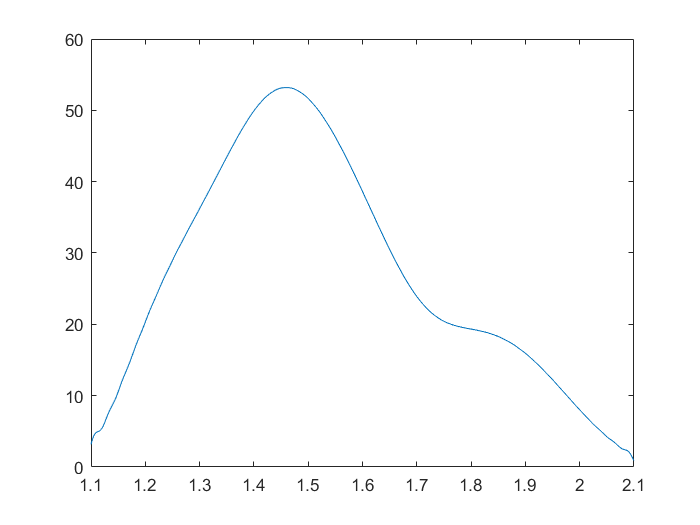

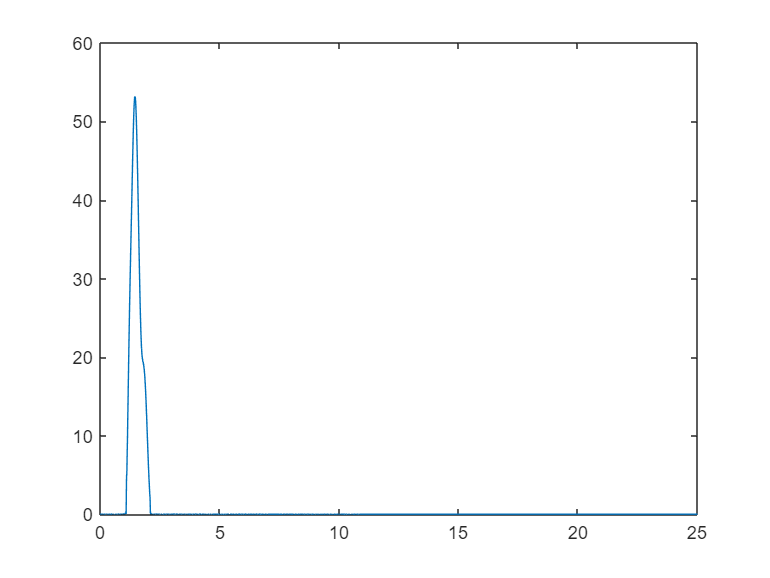

plot(sigma(indix_min:indix_max),abs_fis(indix_min:indix_max));

function ccwl1 = zxf(wl,guass)
P = sum(wl.*guass);
Q = sum(guass);
ccwl1 = P/Q;
end

